## 1)

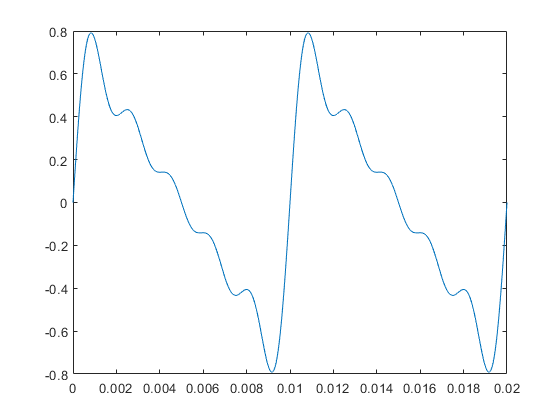

t=0:(1/48000):0.02;
A1=0.5; f1=100;

ysierra= A1*sin(2*pi*f1*t) + A1/2*sin(2*pi*2*f1*t) + A1/3*sin(2*pi*3*f1*t) + A1/4*sin(2*pi*4*f1*t) + A1/5*sin(2*pi*5*f1*t);
plot(t,ysierra)

## 2)

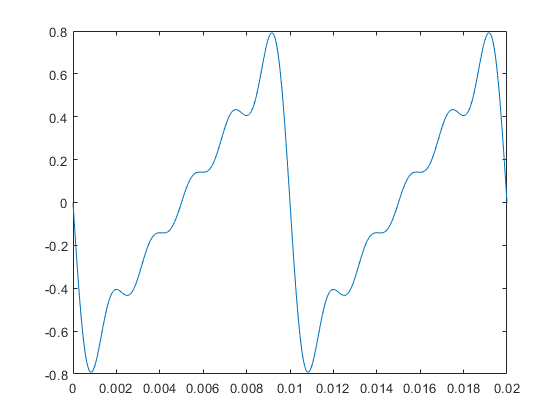

fase=pi;
ysierra= A1*sin(2*pi*f1*t+fase) + A1/2*sin(2*pi*2*f1*t+fase) + A1/3*sin(2*pi*3*f1*t+fase) + A1/4*sin(2*pi*4*f1*t+fase) + A1/5*sin(2*pi*5*f1*t+fase);
plot(t,ysierra)

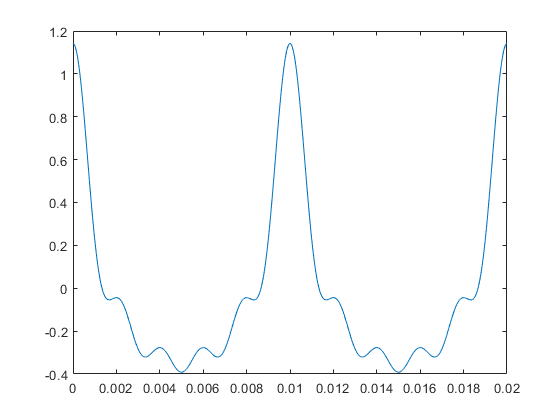

fase=pi/2;
ysierra= A1*sin(2*pi*f1*t+fase) + A1/2*sin(2*pi*2*f1*t+fase) + A1/3*sin(2*pi*3*f1*t+fase) + A1/4*sin(2*pi*4*f1*t+fase) + A1/5*sin(2*pi*5*f1*t+fase);
plot(t,ysierra)

## 3)

yscos=0*t;
for n=1:5
    yscos=yscos+A1/n*cos(2*n*pi*f1*t);   
end

## 4)

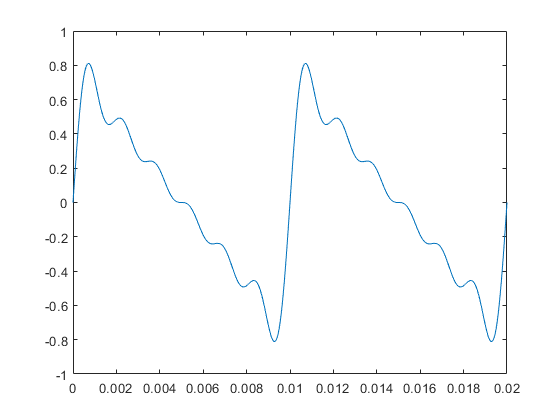

ysierra=0*t; 
for n=1:25
    ysierra=ysierra + A1/n*sin(2*pi*n*f1*t);
     plot(t,ysierra);
     pause(0.3)
     
 end

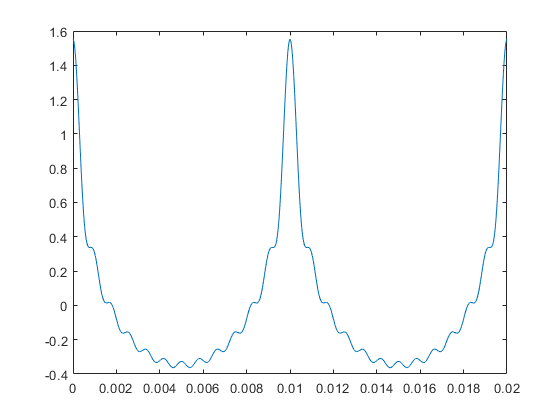

ysierra=0*t; fase=pi/2;
for n=1:25
    ysierra=ysierra + A1/n*sin(2*pi*n*f1*t+fase);
     plot(t,ysierra);
     pause(0.3)
     
 end

## 5)

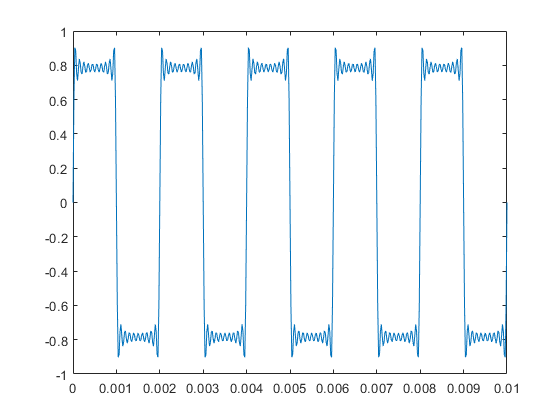

f1=500; A1=1;
t= 0:(1/48000):0.01;
ycuad=0*t;
for n=(1:2:19)
    ycuad=ycuad + A1/n*sin(2*pi*n*f1*t);
    plot(t,ycuad)
    pause(0.3)
end

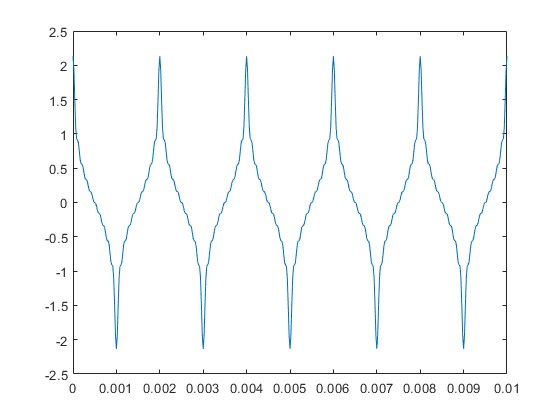

f1=500; A1=1; fase=pi/2;
t= 0:(1/48000):0.01;
ycuadfase=0*t;
for n=(1:2:19)
    ycuadfase=ycuadfase + A1/n*sin(2*pi*n*f1*t+fase);
    plot(t,ycuadfase)
    pause(0.3)
end

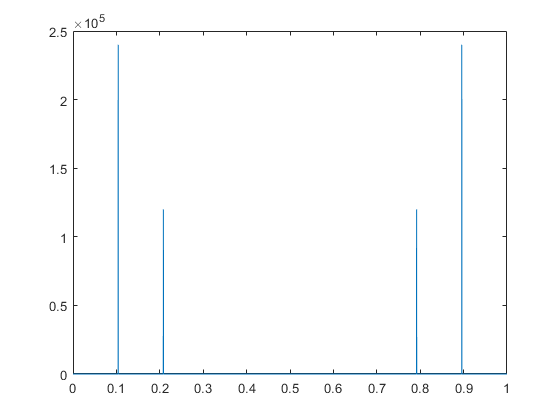

fs=48000;
dt=1/fs;
duracion=1; %segundos
t=0:dt:duracion-dt; %Prestar atención a "duración-dt"
f0=5000;
y=10*sin(2*pi*f0*t)+5*sin(2*pi*2*f0*t);
Fourier=fft(y);
plot(t,abs(Fourier));

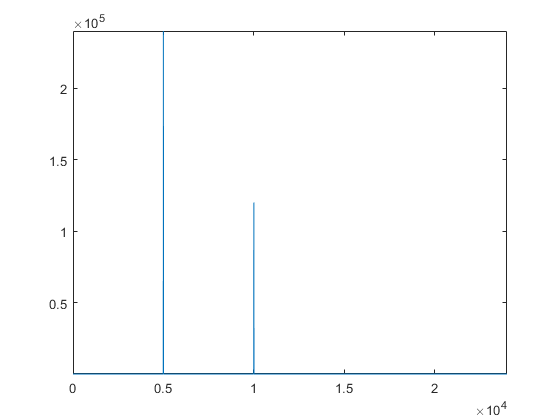

longitud=length(y);
f=(0:longitud-1)/longitud*fs;
plot(f,abs(Fourier))
axis([0 fs/2 -inf inf])

## 6)

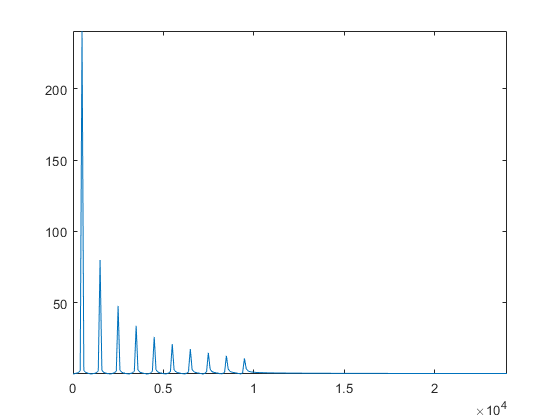

fs=48000;
longitud=length(ycuad);
f=(0:longitud-1)/longitud*fs;
plot(f,abs(fft(ycuad)));
axis([0 fs/2 -inf inf])


plot(f,abs(fft(ycuadfase)));

Undefined function or variable 'ycuadfase'.

## 7)

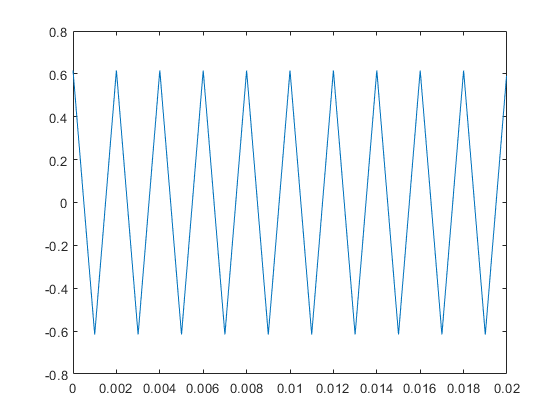

t=0:(1/48000):0.02-(1/48000);
f1=500; a1=0.5;
yT=0*t;
for n=1:2:219
    yT=yT+ a1/(n^2)*cos(2*pi*n*f1*t);
    plot(t,yT)
    %pause(0.3)
end

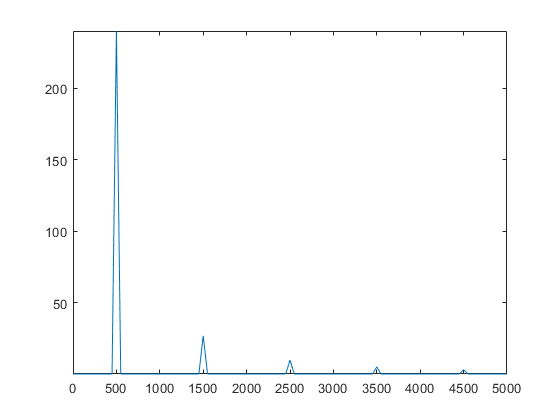

Fft=fft(yT);
longitud=length(yT);
f=(0:longitud-1)/longitud*48000;
plot(f,abs(Fft))
axis([0 5000 -inf inf])

## 8)

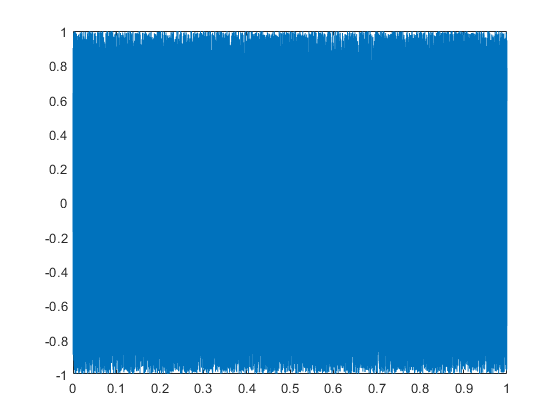

fs=48000;
ruidoBlanco=2*rand(fs,1)-1;
dt=1/fs;
t=0:dt:(fs-1)*dt;
plot(t,ruidoBlanco)

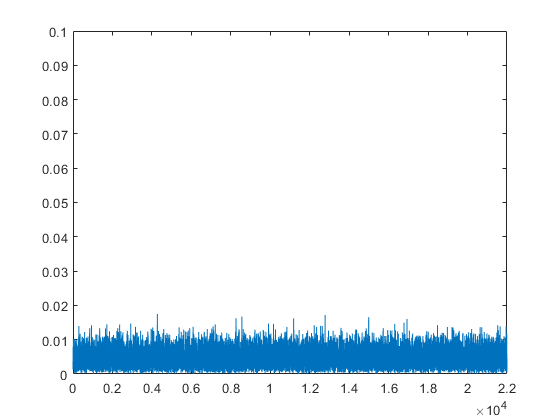


%%sound(RB,fs)
Y=fft(ruidoBlanco);
longitud=length(ruidoBlanco);
f=(0:longitud-1)/longitud*fs;
plot(f,abs(Y)*2/longitud);
axis([0 22000 0 0.1])

## 9)

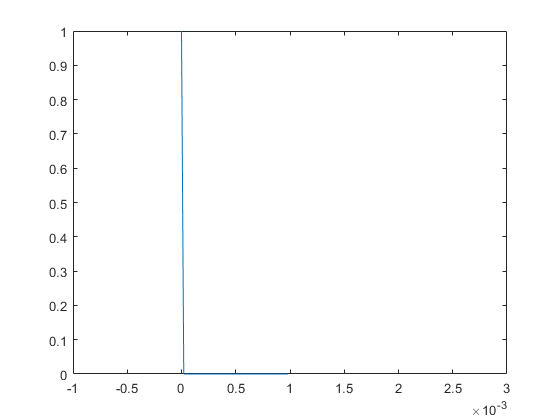

fs=48000;
dt=1/fs;
duracion=0.001;
t=(0:dt:duracion-dt);
longitud=length(t);
impulso=zeros(longitud,1);
impulso(1)=1;
plot(t,impulso)
axis ([-0.001 0.003 0 1])

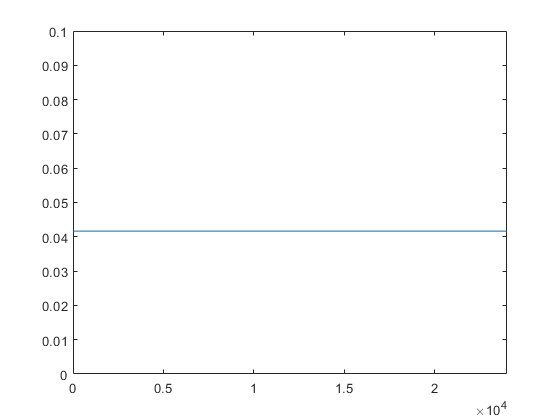


f=(0:longitud-1)/longitud*fs;
Fi=fft(impulso);
plot(f,abs(Fi)*2/longitud)
axis([0 fs/2 0 0.1])